# Beregning til flow i rør - virker lovende

clc; clear all;
u = symunit;


% Data for r134a fra http://www.peacesoftware.de/einigewerte/calc_r134a.php7
rho = 1358.3 * u.kg/u.m^3;
cp = 1.293 * u.kJ/(u.kg*u.K);
beta_v = 2.27 * 10^(-3) * 1/u.K;
lambda = 102.4 *1e-3 * u.W/(u.m*u.K);

eta = 337.2 *1e-6 * u.Pa * u.s; % Viskositet 
nu = 2.48 * 10^(-6) * u.m^2/u.s; % Kinematisk viskositet for vand

a = 0.131 * 10^(-6) * u.m^2/u.s; % Temperaturledetal

Prandtls_tal = 13;

% Flowrate til hastighed for r134a
Q = 0.000507 * u.m^3/u.s; 
di = 10 * u.mm;
A = pi * di^2/4;
vi = Q/A;
vi = vpa(unitConvert(vi, "SI"), 3)

$$vi = 6.46\,\frac{m}{s}$$


% Data for cylinder - Beholder volumen
% slush = 0.5;   % 1 liter
% s_m3 = 0.0005 * u.m^3;  % liter til m3
% D_beholder = 10 * u.cm;
% r = D_beholder/2;    % radius på beholder
% h_b = s_m3/(pi*r^2);
L = di % højde på beholder

$$L = 10\,\mathrm{mm}$$


c = vi; % omrøringshastighed

% Data for temperaturer
tfl = -2;
tv = -4;
delta_t = (tfl + tv) * u.K;


% Konstanter
g = 9.81 * u.m/u.s^2;


% Beregningstal
Re = c*L/nu;
Re = vpa(unitConvert(Re, "SI"), 5)

$$Re = 26030.0$$


% Der er antaget temperaturer
Gr = g*L^3*beta_v*delta_t/(nu^2);
Gr = vpa(unitConvert(Gr, "SI"), 5)

$$Gr = -21724.0$$


Pr = eta*cp/lambda;
Pr = vpa(unitConvert(Pr, "SI"), 5)

$$Pr = 4.2578$$


Ra = Gr*Pr;
Ra = vpa(unitConvert(Ra, "SI"), 7)

$$Ra = -92497.26$$

% Beregnings af Nusselts tal v. turbulent strømning i slushice
% der antages en dynamisk viskositet ved væg temperatur

%eta_v = eta * 2;
%K1 = (eta/eta_v)^(0.14);
%K2 = (1 + (D_beholder/L)^(2/3));


Nu = 0.664*Re^(1/2)*Pr^(1/3)

$$Nu = 173.63208859137023398799604551118$$

Nu = vpa(unitConvert(Nu, "SI"), 4)

$$Nu = 173.6$$

% Beregning af varmeovergangstal

alpha = Nu*lambda/L;
alpha = vpa(unitConvert(alpha, u.W/u.K), 4)

$$alpha = 1778.0\,\frac{W}{K\,m^{2}}$$


% Passer ikke til inde i røret
% A1 = D_beholder * pi * L;
% A1 = vpa(unitConvert(A1, "SI"), 5)
% 
% 
% R1 = 1/(alpha*A1);
% R1 = vpa(R1, 3)



x_indl = vpa(0.05*Re/di, 3)     % Hydrodynamisk indløbsstrækning

$$x\_indl = 130.0\,\frac{1}{\mathrm{mm}}$$

r = -20 * u.K;
g = 9.81 * u.m/u.s;

syms L

lambda_g = 0.05327 * u.W/(u.m*u.K);

clc; clear all;

% Bo Pierres metode
syms r L g Re alpha di

Kf = r/(L*g);

% Nusselts tal
syms r1 r2 r3 r4 Acyl lambda_k lambda_g alpha_br alpha_sl Aglas T1 T5 Phi
Nu = 0.0009*Re*Kf^(1/2)

$$Nu = \frac{9\,\text{Re}\,\sqrt{\frac{r}{L\,g}}}{10000}$$


% Resistens formler
R1 = 1/(alpha*2*pi*di)

$$R1 = \frac{1}{2\,\alpha \,\mathrm{di}\,\pi }$$


R2 = (r2/r1)/(lambda_k * 2*pi*L)

$$R2 = \frac{r_{2}}{2\,L\,\lambda_{k}\,r_{1}\,\pi }$$


R3 = 1/(alpha_br*Acyl)

$$R3 = \frac{1}{\mathrm{Acyl}\,\alpha_{\mathrm{br}}}$$


R4 = (r4/r3)/(lambda_g * 2*pi*L)

$$R4 = \frac{r_{4}}{2\,L\,\lambda_{g}\,r_{3}\,\pi }$$


R5 = 1/(alpha_sl * Aglas)

$$R5 = \frac{1}{\mathrm{Aglas}\,\alpha_{\mathrm{sl}}}$$


R_tot = (T1 - T5)/Phi

$$R\_tot = \frac{T_{1}-T_{5}}{\Phi }$$

clc; clear all;
u = symunit;


% Bo Pierre tal
r = -20 * u.K;
g = 9.81 * u.m/u.s^2;

%syms L_ror  % Vores eneste ukendte
L_ror = 5*u.m

$$L\_ror = 5\,m$$

% Radii
r1 = 10*u.mm;
r2 = 12*u.mm;
r3 = 12*u.cm;
r4 = 13*u.cm;

% Arealer
Lglasind = 10*u.cm;
Lglasud = 15*u.cm;

Aglasud = 2*pi*r4*Lglasud;

Aglasind = 2*pi*r3*Lglasind;

A_ror = 2*pi*r1*L_ror;

% Varmekonduktiviteter
lambda_g = 0.05327 * u.W/(u.m*u.K); % glas 
lambda_k = 1 * u.W/(u.m*u.K);       % kobber

% Varmeovergangstal
alpha_sl = 4688 *u.W*u.K * u.m^2;
alpha_br = 58.14 * u.W * u.K * u.m^2;
alpha_r134 = 1778 * u.W * u.K * u.m^2;

% Temp og Phi
T1 = -20*u.K;
T5 = -2*u.K;
Phi = 480*u.W;

Re = 26030;




% Bo Pierres metode


Kf = r/(L_ror*g);

% Nusselts tal
Nu = 0.075*(Re^2*Kf)^(0.4);
Nu = vpa(unitConvert(Nu, "SI"), 4)

$$Nu = 0.075\,{\left(-2.763e+8\,\frac{K\,s^{2}}{m^{2}}\right)}^{2/5}$$


% Resistens formler
R1 = 1/(alpha_r134*A_ror)

$$R1 = \frac{1}{177800\,\pi }\,\frac{1}{K\,W\,m^{3}\,\mathrm{mm}}$$


R2 = (r2/r1)/(lambda_k * 2*pi*L_ror)

$$R2 = \frac{3}{25\,\pi }\,\frac{K}{W}$$


R3 = 1/(alpha_br*Aglasud)

$$R3 = \frac{5}{113373\,\pi }\,\frac{1}{K\,W\,{\mathrm{cm}}^{2}\,m^{2}}$$


R4 = (r4/r3)/(lambda_g * Aglasind)

$$R4 = \frac{8125}{95886\,\pi }\,\frac{K\,m}{W\,{\mathrm{cm}}^{2}}$$


R5 = 1/(alpha_sl * Aglasind)

$$R5 = \frac{1}{1125120\,\pi }\,\frac{1}{K\,W\,{\mathrm{cm}}^{2}\,m^{2}}$$

    
R_tot1 = R1+R2+R3+R4+R5

$$R\_tot1 = \frac{3}{25\,\pi }\,\frac{K}{W}+\frac{8125}{95886\,\pi }\,\frac{K\,m}{W\,{\mathrm{cm}}^{2}}+\frac{1912991}{42519409920\,\pi }\,\frac{1}{K\,W\,{\mathrm{cm}}^{2}\,m^{2}}+\frac{1}{177800\,\pi }\,\frac{1}{K\,W\,m^{3}\,\mathrm{mm}}$$

R_tot = (T1 - T5)/Phi

$$R\_tot = -\frac{3}{80}\,\frac{K}{W}$$

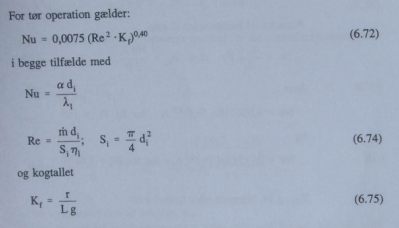

clc; clear all;
u = symunit;

Re = 26030;

alpha_r134 = 1778 %* u.W * u.K * u.m^2;

alpha_r134 = 1778


di = 0.010%*u.mm;

di = 0.0100


lambda = 102.4 *1e-3 %* u.W/(u.m*u.K);

lambda = 0.1024


r = 20%*u.K;

r = 20


g = 9.81 %* u.m/u.s^2;

g = 9.8100


syms L

Nu = alpha_r134*di/lambda

Nu = 173.6328

Kf = r/(L*g);

eq = Nu == 0.075*(Re^2*Kf)^(0.4);

L = solve(eq, L);
L = vpa(unitConvert(L, "SI"), 4)

$$L = 5.357$$